**Demonteeri CSV fail Matlabile sobivateks maatriksiteks**

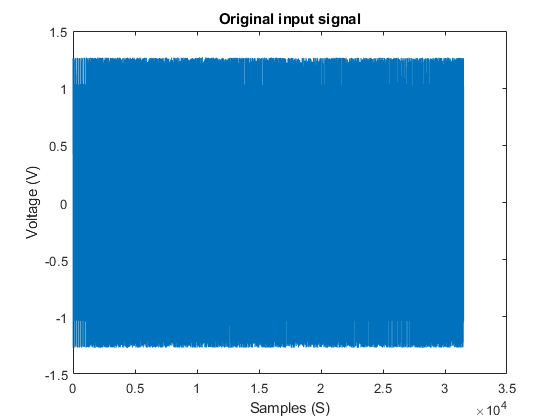

clear;
close all;

rawdata = readtable('data/rawdata.csv', "PreserveVariableNames",false);
    
voltage = rawdata(:, 3);
voltage = voltage{:, :};
time = rawdata(:, 2);
time = time{:, :};

figure;
plot(voltage)
title('Signaal modulatsiooniga')
xlabel('Mõõtetulemused (S)')
ylabel('Pinge (V)')

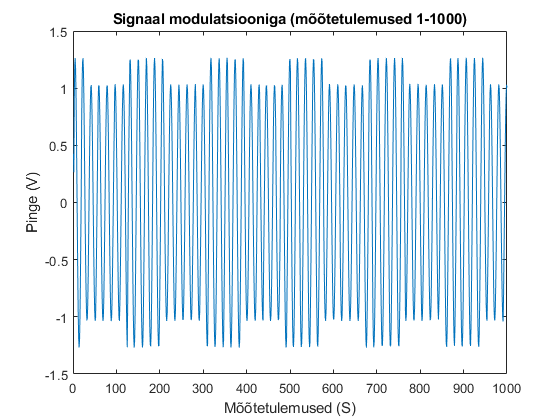


figure;
plot(voltage(1:1000))
title('Signaal modulatsiooniga (mõõtetulemused 1-1000)')
xlabel('Mõõtetulemused (S)')
ylabel('Pinge (V)')


warning('off','all')

**Leia terve signaali sageduste spekter kasutades FFT teisendust**

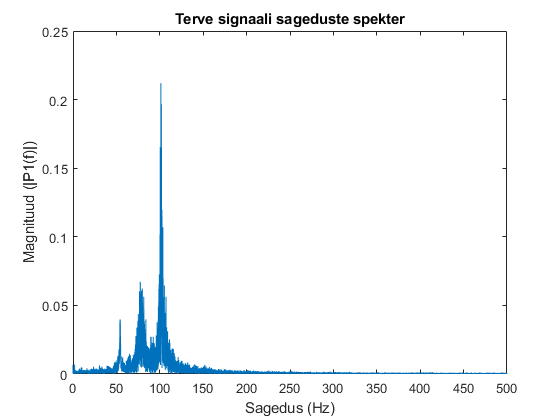

T = 0.001;
Fs = 1/T;   
L = length(voltage);
t = (0:L-1)*T;
f = Fs*(0:(L/2))/L;

fft_volt = fft(voltage);
P2 = abs(fft_volt)/L;
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

figure;
plot(f,P1) 
title('Terve signaali sageduste spekter')
xlabel('Sagedus (Hz)')
ylabel('Magnituud (|P1(f)|)')

**Leia signaali nullpunktid kasutades "zero-crossing" meetodit**

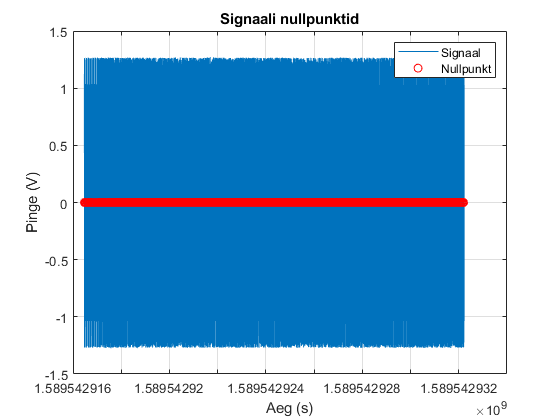

UpZCi = @(v) find(v(1:end-1) <= 0 & v(2:end) > 0);
DownZCi = @(v) find(v(1:end-1) >= 0 & v(2:end) < 0);
ZeroX = @(x0,y0,x1,y1) x0 - (y0.*(x0 - x1))./(y0 - y1);

ZXi = sort([UpZCi(voltage'),DownZCi(voltage')]);
ZX = ZeroX(time(ZXi),voltage(ZXi),time(ZXi+1),voltage(ZXi+1));

if voltage(end)==0
    ZX(end+1) = t(end);
end

figure;
plot(time, voltage)
hold on;
plot(ZX,zeros(1,length(ZX)),'ro')
grid on;
legend('Signaal', 'Nullpunkt')
title('Signaali nullpunktid')
xlabel('Aeg (s)')
ylabel('Pinge (V)')

**Kasuta "wavelet" funktsiooni, et eemaldada peasagedus (100 Hz) ja jäta alles vaid muud sagedused**

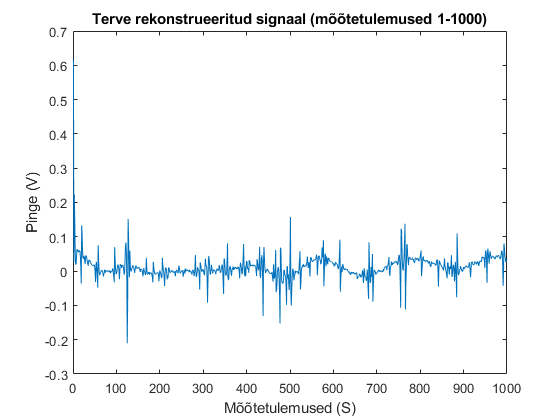

levelForReconstruction = [true, true, false, false, false, false, true, true, true, true, true, true, true, true, true];
wt = modwt(voltage, 'sym4', 14);
mra = modwtmra(wt, 'sym4');
voltage1 = sum(mra(levelForReconstruction,:),1);

figure;
plot (voltage1(1:1000))
title("Terve rekonstrueeritud signaal (mõõtetulemused 1-1000)")
ylabel("Pinge (V)")
xlabel("Mõõtetulemused (S)")

**Leia modulatsiooni signaali sageduste spekter 10 perioodi kohta**

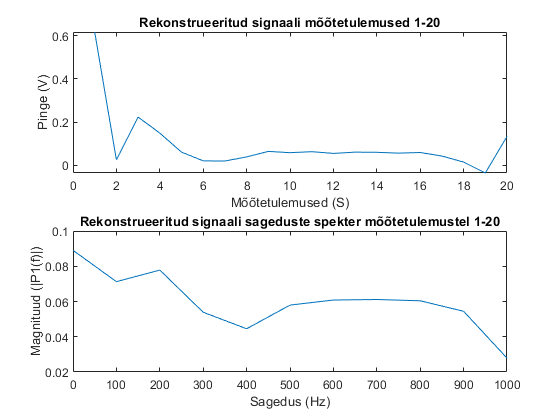

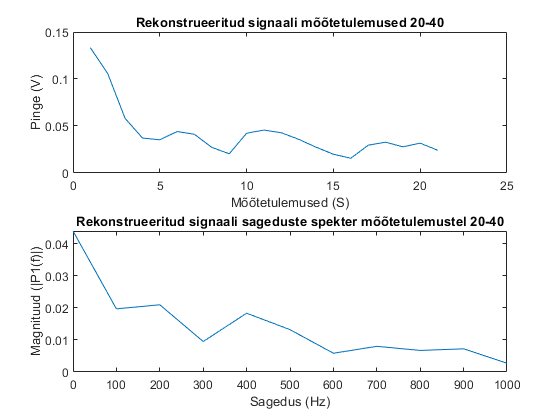

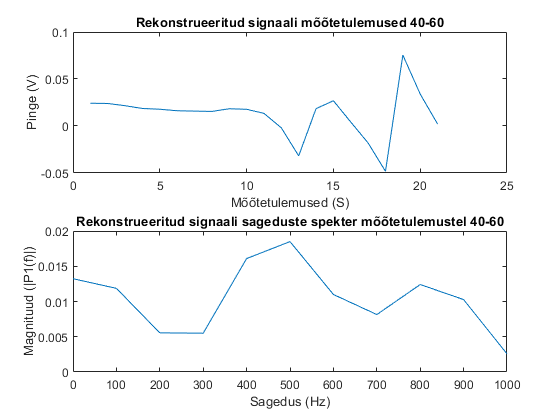

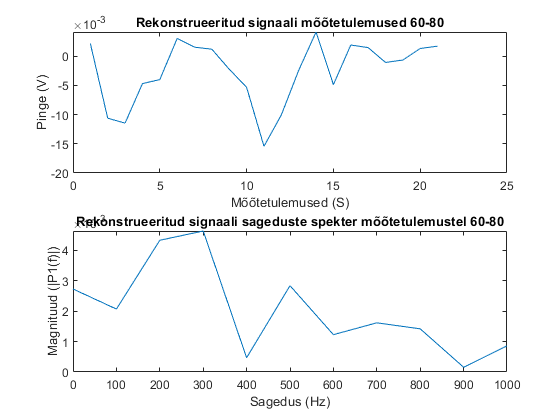

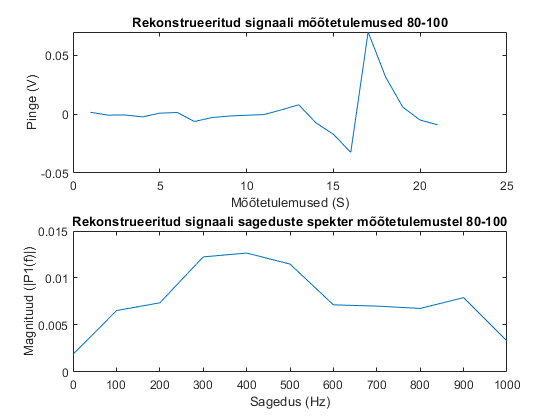

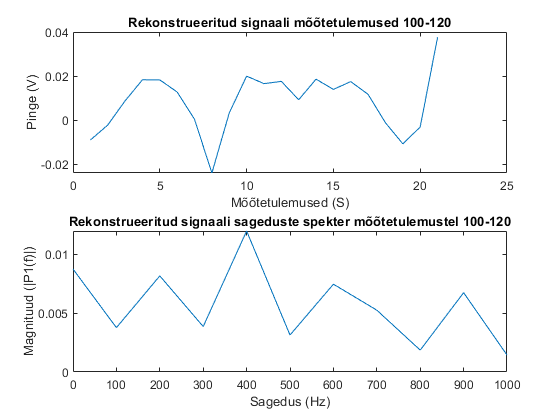

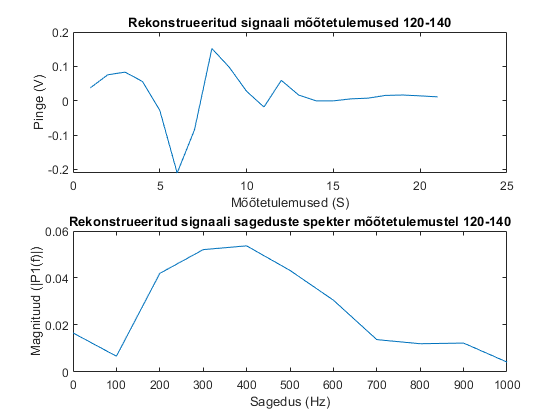

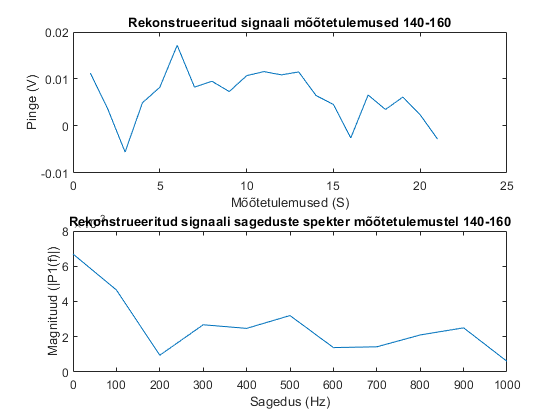

q = 10;
m = 1;
n = 20;

for k = 1:q
    voltage_ind = voltage1(m:n);
    
    T_ind = 0.0005;
    Fs_ind = 1/T_ind;
    L_ind = 20;
    t_ind = (0:L_ind-1)*T_ind;
    f_ind = Fs_ind*(0:(L_ind/2))/L_ind;
    
    fft_volt_ind = fft(voltage_ind);
    P2_ind = abs(fft_volt_ind)/L_ind;
    P1_ind = P2_ind(1:L_ind/2+1);
    P1_ind(2:end-1) = 2*P1_ind(2:end-1);
    
    figure;
    subplot(2,1,1)
    plot (voltage1(m:n))
    title("Rekonstrueeritud signaali mõõtetulemused " + num2str(m) + "-" + num2str(n))
    ylabel("Pinge (V)")
    xlabel("Mõõtetulemused (S)")
    subplot(2,1,2)
    plot(f_ind, P1_ind)
    title("Rekonstrueeritud signaali sageduste spekter mõõtetulemustel " + num2str(m) + "-" + num2str(n))
    xlabel("Sagedus (Hz)")
    ylabel("Magnituud (|P1(f)|)")
    
    m=n;
    n=n + 20;
end

**Leia pinge RMS väärtus ja sageduste spekter 50 perioodi kohta**

q = 50;
m = 20;
n = 40;

rms_volt = zeros(1, q);
periods = zeros(1, q);
fft_total = zeros(q, 11);

for k = 1:q
    voltage_ind = voltage(m:n);
    
    periods(k) = k;
    rms_volt_ind = sqrt((sum(voltage_ind.^2))/length(voltage_ind));
    rms_volt(k) = rms_volt_ind;
    
    T_ind = 0.0005;
    Fs_ind = 1/T_ind;
    L_ind = 20;
    t_ind = (0:L_ind-1)*T_ind;
    f_ind = Fs_ind*(0:(L_ind/2))/L_ind;
    
    fft_volt_ind = fft(voltage_ind);
    P2_ind = abs(fft_volt_ind)/L_ind;
    P1_ind = P2_ind(1:L_ind/2+1);
    P1_ind(2:end-1) = 2*P1_ind(2:end-1);
    fft_total(k, :) = P1_ind';
    
%     figure;
%     subplot(2,1,1)
%     plot(voltage(m:n))
%     title("Real time voltage from samples " + num2str(m) + "-" + num2str(n))
%     ylabel("Voltage (V)")
%     xlabel("Samples (S)")
%     subplot(2,1,2)
%     plot(f_ind, P1_ind)
%     title("Single-sided amplitude spectrum from samples " + num2str(m) + "-" + num2str(n))
%     xlabel('Frequency (Hz)')
%     ylabel('Magnitude (|P1(f)|)')
    
    m=n;
    n=n + 20;
end

**Loo maatriksid perioodide, pinge RMS ja FFT väärtuste kohta ja sageduste kohta**

maindata = zeros(q, 23);
maindata(1:q, 1) = periods';
maindata(1:q, 2) = rms_volt';
maindata(:, 3:13) = fft_total;

metadata = zeros(5, 11);
metadata(1, 1) = T_ind;
metadata(2, 1) = Fs_ind;
metadata(3, 1) = L_ind;
metadata(4, 1:11) = f_ind;

csvwrite("data\maindata.csv", maindata);
csvwrite("data\metadata.csv", metadata);

**Loo pinge RMS ja FFT tulemuste graafik**

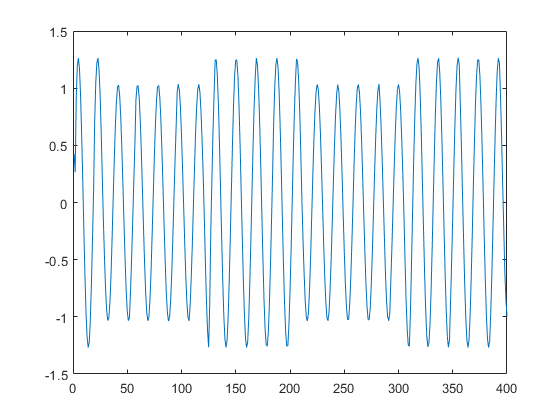

figure;
plot(voltage(1:400))

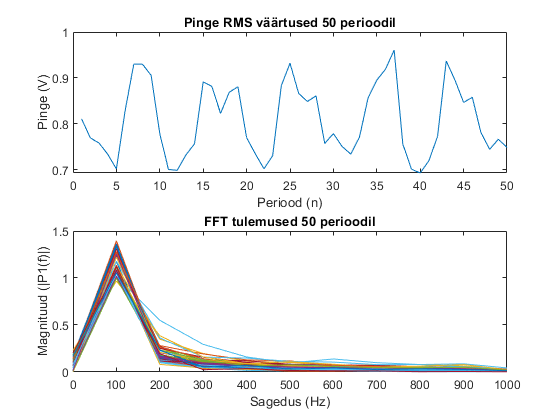


figure;
subplot(2,1,1)
plot(maindata(:, 1), maindata(:, 2))
title("Pinge RMS väärtused " + num2str(length(periods)) + " perioodil")
ylabel("Pinge (V)")
xlabel("Periood (n)")
subplot(2,1,2)
plot(metadata(4, 1:11), maindata(:, 3:13))
title("FFT tulemused " + num2str(length(periods)) + " perioodil")
xlabel("Sagedus (Hz)")
ylabel("Magnituud (|P1(f)|)")